# Aula 10 - Teorema de Nyquist

Determine o intervalo de K para a estabilidade em malha fechada da função de transferência abaixo, através do Terorema de Nyquist. Em seguida, confirme os resultados pelo Lugar das Raizes. 


$$G(s)=\frac{K}{s(s+1)(2s+1)}$$


### Verificação dos pólos em malha aberta

close all
clear
s=tf([1 0],1)

s =
 
  s
 
Continuous-time transfer function.



G=1/(s*(s+1)*(2*s+1))

G =
 
          1
  -----------------
  2 s^3 + 3 s^2 + s
 
Continuous-time transfer function.



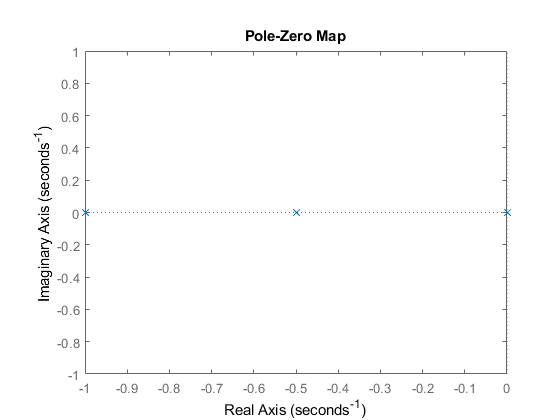

pzmap(G)

Para estabilidade,** Z=N+P=0**, sendo **Z** o número de** pólos em malha fechada** no SPD, **N** o **número de envoltórias no sentido horário** no ponto -1 do diagrama de nyquist e** P** o número de **pólos em malha aberta** no SPD.

Como visto no gráfico acima, P=0. Logo, para Z=0, N=0.

### Algumas contas importantes antes do Diagrama de Nyquist

Fazendo $s=j\omega$ temos

syms w K
s=j*w;
den_jw=2*s^3+3*s^2+s

$$den\_jw = -2\,w^{3}\,\mathrm{i}-3\,w^{2}+w\,\mathrm{i}$$


$$G(j\omega)=\frac{K}{-2j\omega^3-3\omega^2+j\omega}$$


Como $n>m$, $\lim_{\omega\rightarrow\infty}|G(j\omega)|=0$

Como $n-m=3$ (nº de polos - nº de zeros), para $\omega\rightarrow\infty$ o diagrama tende a zero por -270º (eixo imaginário positivo).

Como o sistema é **tipo 1**, para $\omega=0$ o diagrama começa com módulo tendendo a $\infty$ e com fase -90º.

Para que o diagrama cruze o eixo real, a parte imaginária de $G(j\omega)$ deve ser nula, ou seja, $-2\omega^3+\omega=0$. Então, $\omega=0$ ou $-2\omega^2+1=0$, que dá $\omega=\pm \frac{1}{\sqrt{2}} \approx \pm 0.7071$. 

w=1/sqrt(2);
G_1_raizde2=K/subs(den_jw)

$$G\_1\_raizde2 = -\frac{2\,K}{3}$$

Fazendo K=1, temos que o diagrama irá cruzar o eixo real em $G(j\omega=\frac{1}{\sqrt{2}})=-\frac{2}{3}\approx0.667$. Como esse ponto é proporcional a K, se queremos que o Diagrama não englobe o ponto -1 (N=0) temos que fazer $-\frac{2K}{3}>-1$, o que nos dá $K<\frac{3}{2}$. 

Logo, $0<K<\frac{3}{2}$.

### Plotagem do Diagrama de Nyquist para K=1, e K=3/2

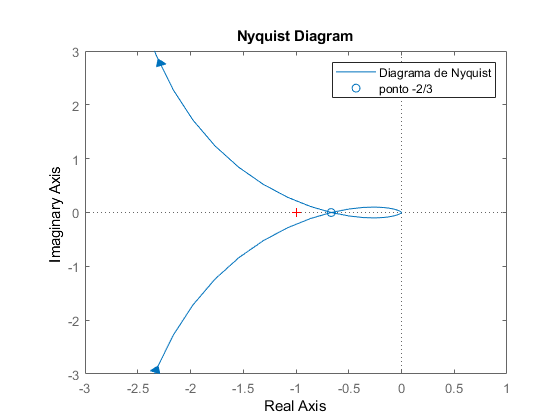

% K=1
nyquist(G)
hold on
scatter(-2/3,0)
axis([-3 1 -3 3])
legend("Diagrama de Nyquist","ponto -2/3")
hold off

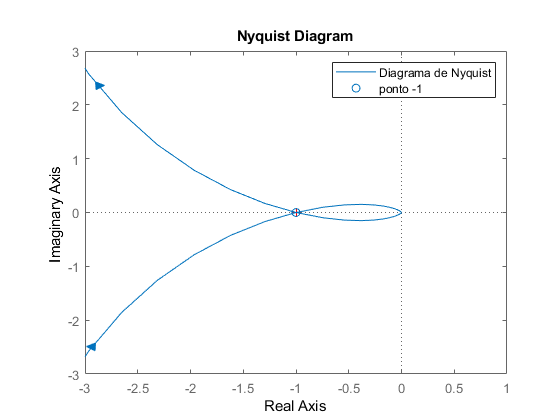

% K=3/2
nyquist(3/2*G)
hold on
scatter(-1,0)
axis([-3 1 -3 3])
legend("Diagrama de Nyquist","ponto -1")
hold off

### Verificação por Lugar das Raízes

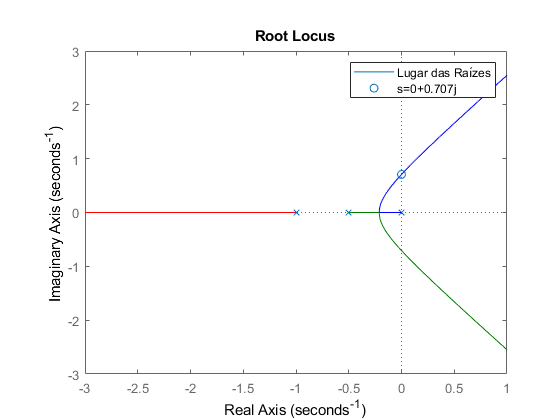

rlocus(G)
hold on
scatter(0,1/sqrt(2))
axis([-3 1 -3 3])
legend("Lugar das Raízes","s=0+0.707j")
hold off

Como o *Live Script* não mostra o valor de K como em um plot interativo, o cálculo será feito manualmente, aplicando a condição de módulo no ponto $s=0+\frac{1}{\sqrt{2}}j$, que é onde o LR cruza o eixo imaginário positivo.

%Eixo imaginário positivo
s=0+1/sqrt(2)*j;
K=abs(2*s^3+3*s^2+s)

K = 1.5000

Como podemos ver, $K=1,5=\frac{3}{2}$. Logo, $0<K<\frac{3}{2}$.